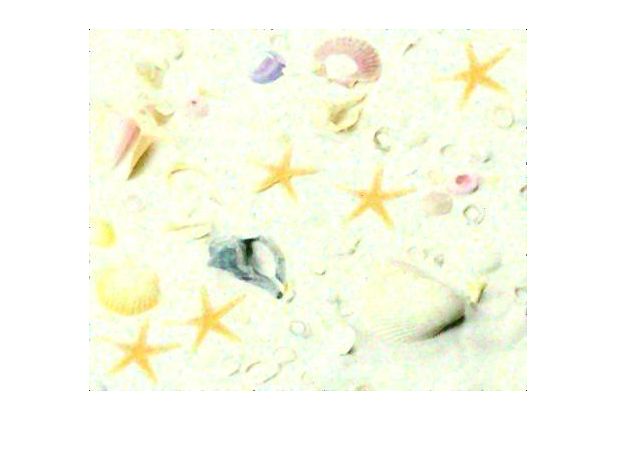

% Computer Vision Coursework Pipeline
% Write the file name to load below, with the extesion, It will
% be expected that it is located within the current directory
FileName = "StarFish_map2.jpg";
%FileName = "starfish_5.jpg";
%Image Variable that will not be editied (Original)
OriginalImage = LoadImage(FileName);

The first task, after loading the image is to analyse the image histogram and decide what to do with the image

DeSaturisedImage = 362×438 uint8 matrix
     0    32   255    61   239    53   239    73   174   174   174   174   174   174   210   210   174   142   174   174   174   210   210   210   239   210   210   174   174   174   142   113   174   174   210   210   210   210   210   174   113   142   142   174   174   142   142   113    49    45
    40   255    81   239   239    32   239   210   174   174   174   174   174   174   174   210   174   174   174   174   210   210   210   210   239   239   210   210   210   174   142   142   174   210   210   210   210   210   210   174   142   142   174   174   174   174   142   142    81    65
   255    81    53   255   239   210   239    61   142   142   142   174   174   174   174   210   210   174   174   210   174   210   210   210   239   239   210   210   210   174   174   174   174   210   210   210   210   174   174   142   142   142   174   174   174   174   174   142   113   113
    45    65   255   239    36   239   239    97   142   

GrayFilteredImage = 362×438 logical array
   1   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   1   1   1
   1   0   1   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1
   0   1   1   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1
   1   1   0   0   1   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

GrayFilteredImage = 362×438 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

GrayFilteredImage =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     

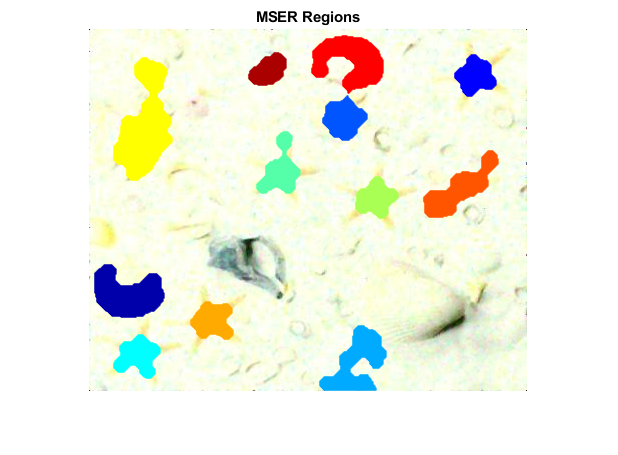

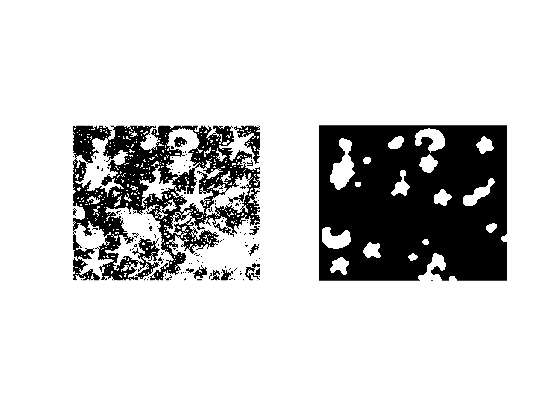

1: BoudningBox:  X: 25.5 Y: 29.5 Eccentricity: 0.92692 Solidity: 0.75651 Area: 3775
2: BoudningBox:  X: 366.5 Y: 26.5 Eccentricity: 0.2731 Solidity: 0.89147 Area: 1035
3: BoudningBox:  X: 335.5 Y: 122.5 Eccentricity: 0.95699 Solidity: 0.76478 Area: 1824
4: BoudningBox:  X: 267.5 Y: 148.5 Eccentricity: 0.48609 Solidity: 0.88255 Area: 1052
5: BoudningBox:  X: 231.5 Y: 297.5 Eccentricity: 0.84185 Solidity: 0.69961 Area: 1989
6: BoudningBox:  X: 234.5 Y: 67.5 Eccentricity: 0.22085 Solidity: 0.91994 Area: 1218
7: BoudningBox:  X: 223.5 Y: 7.5 Eccentricity: 0.74807 Solidity: 0.74862 Area: 2311
8: BoudningBox:  X: 168.5 Y: 103.5 Eccentricity: 0.83193 Solidity: 0.70136 Area: 1240
9: BoudningBox:  X: 160.5 Y: 24.5 Eccentricity: 0.79226 Solidity: 0.95579 Area: 800
10: BoudningBox:  X: 102.5 Y: 273.5 Eccentricity: 0.44755 Solidity: 0.85614 Area: 1095
11: BoudningBox:  X: 25.5 Y: 306.5 Eccentricity: 0.48354 Solidity: 0.8069 Area: 1170
12: BoudningBox:  X: 6.5 Y: 236.5 Eccentricity: 0.7973 Solidity

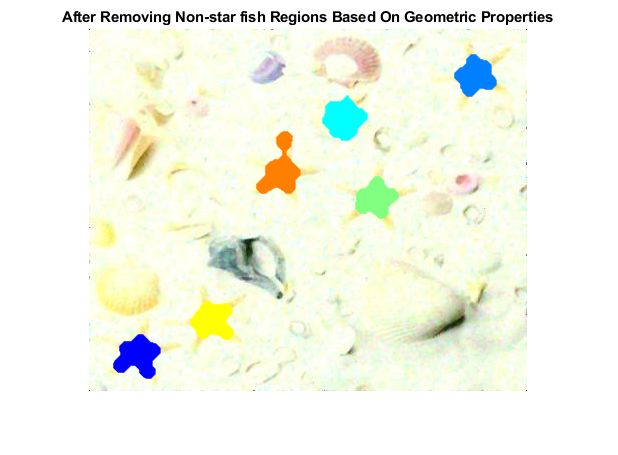

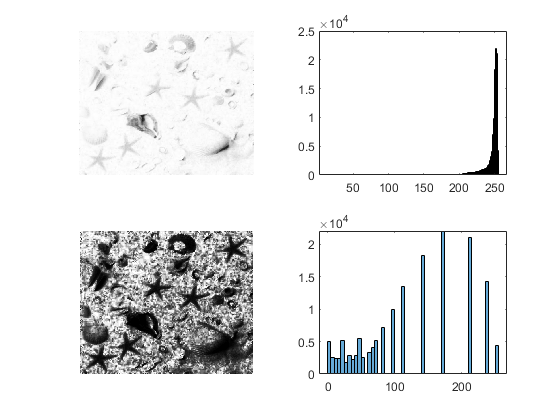

if (true) 
    DeSaturisedImage = deSaturisedImage(OriginalImage)
    GrayFilteredImage = saturisedImageCleanUp(DeSaturisedImage);
    saturisedImageAnalsys(GrayFilteredImage, OriginalImage);
else 
    DeSaltedImage = deSaltImage(OriginalImage);
    GrayFilteredImage = createMask(DeSaltedImage);
    figure
    imshow(GrayFilteredImage);
    standardImageAnalysis(GrayFilteredImage, OriginalImage);
end


%imshow(imbinarize(GreyFilteredImage,graythresh(GreyFilteredImage)));

## Now moving from image prepocessing to image analysis

%This is a basic outline and may change later
SE = strel('diamond',3);
circle = strel('disk', 3, 4);
smallOct = strel('octagon', 3)

smallOct = strel is a octagon shaped structuring element with properties:

      Neighborhood: [7×7 logical]
    Dimensionality: 2


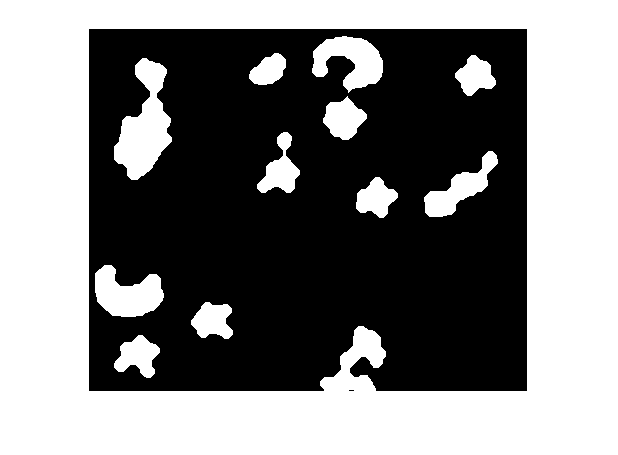

starAttempt = [1,0,0,0,0,1,0,0,0,0,1,
               0,1,0,0,0,1,0,0,0,1,0,
               0,0,1,0,0,1,0,0,1,0,0,
               0,0,0,1,0,1,0,1,0,0,0,
               0,0,0,0,1,1,1,0,0,0,0,
               1,1,1,1,1,1,1,1,1,1,1,
               0,0,0,0,1,1,1,0,0,0,0,
               0,0,0,1,0,1,0,1,0,0,0,
               0,0,1,0,0,1,0,0,1,0,0,
               0,1,0,0,0,1,0,0,0,1,0,
               1,0,0,0,0,1,0,0,0,0,1];
verySmallStar = [0,1,0,
                        1,1,1,
                        0,1,0];
figure
stepZero = bwareaopen(GrayFilteredImage, 700);
imshow(stepZero);

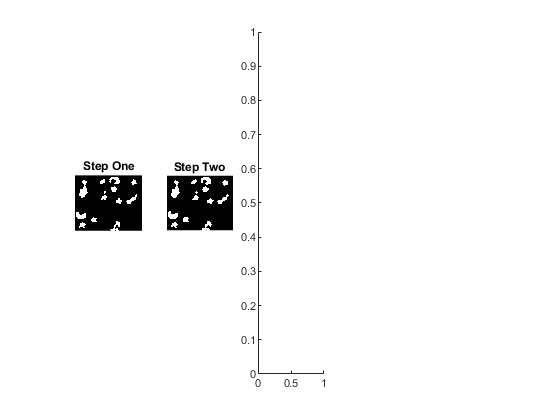

figure
%stepOne = imerode(imclose(GrayFilteredImage, SE),circle);
%imshow(imerode(imopen(imdilate(stepOne, SE),circle),smallOct));
%


stepOne = imopen(imclose(imerode(stepZero, verySmallStar),verySmallStar),circle);
subplot(1,5,1);
imshow(stepOne);
title("Step One")
stepTwo = imdilate(imdilate(imerode(stepOne, circle), verySmallStar), circle);
subplot(1,5,2);
imshow(stepTwo);
title("Step Two")
subplot(1,5,3);

imshow(stepFour);

Unrecognized function or variable 'stepFour'.

title("Step Three");
stepFour = imclose(imerode(stepThree, verySmallStar),verySmallStar);
subplot(1,5,4);
stepFive = imopen(imerode(stepFour, verySmallStar), circle);
imshow(stepFive);
title("Step Four");
stepSix = stepFive;
for x = 1:3
    stepSix = imerode(stepSix, verySmallStar);
end
for x = 1:3
    stepSix = imdilate(stepSix, verySmallStar);
end
subplot(1,5,5);
imshow(stepSix);
title("Step Six");

figure
imshow(stepSix);